## Kalman Filter

#### Load Data

clear; 
clear all; 
close all;

% Read data files
load('.\Data\data_task1_1.mat')

Approach 1:

### Obtaining a Linear Discrete-time System

#### Step 1: Linearise

Convert the non-linear continous-time system to linear continous-time system using Jacobian Linearisation.

syms x w
x_dot = -3* cos ( x ) ^3+ w

$$x\_dot = w-3\,{\cos\left(x\right)}^{3}$$

A_expression = jacobian ( x_dot , x )

$$A\_expression = 9\,{\cos\left(x\right)}^{2}\,\sin\left(x\right)$$

G_expression = jacobian ( x_dot , w )

$$G\_expression = 1$$

A = double ( subs ( A_expression ,x ,0) )

A = 0

G = double ( subs ( G_expression ,[ x w ] ,[0 0]) )

G = 1

#### Step 2: Discretise

Convert the linear continous-time system into linear discrete-time system.

Ts = dt ; % sampling time
[ Phi , Gamma ]= c2d (A ,G , Ts )

Phi = 1

Gamma = 0.0100

#### Kalman Filter:

% Initialization
Ts = dt ;
xhat_km1_km1 = Ex_0 ; % x (0|0) = E{x_0 }
P_km1_km1 = P_0 ; % P (0|0) = P(0)
Q = stdw ^2;
R = stdv ^2;

n = length ( xhat_km1_km1 ) ; % n: state dimension
m = size ( z_k , 1) ; % m: observation dimension

% From linear discrete - time dynamics and observation equations
Phi =1;
Gamma =0.01;
H =1;

% Preallocate storage
stdx_cor = zeros (N , n ) ;
x_cor = zeros (N , n ) ;
K_k = cell (N , 1) ;
innov = zeros (N , m ) ;

for k =1: N
    % Step 1: Prediction
    xhat_k_km1 = Phi * xhat_km1_km1 ; % x(k|k -1) ( prediction )
    z_k_km1 = H * xhat_k_km1 ; % z(k|k -1) ( prediction )

    % Step 2: Covariance matrix of state prediction error
    P_k_km1 = Phi * P_km1_km1 * Phi' + Gamma * Q * Gamma';

    % Step 3: Kalman Gain
    Ve = ( H * P_k_km1 * H' + R ) ; % Pz(k|k -1)
    K = P_k_km1 * H' / Ve ; % K(k) ( gain )

    % Step 4: Measurement Update ( Correction )
    xhat_k_k = xhat_k_km1 + K * ( z_k ( k ) - z_k_km1 ) ;

    % Step 5: Correction for Covariance matrix of state Estimate error
    I_KH = eye ( n ) - K * H ;
    P_k_k = I_KH * P_k_km1 * I_KH' + K * R * K';

    % Save data : State estimate and std dev
    stdx_cor (k ,:) = sqrt ( diag ( P_km1_km1 ) ) ;
    x_cor (k ,:) = xhat_km1_km1 ;
    K_k {k ,1} = K ;
    innov (k ,:) = z_k ( k ) - z_k_km1 ;

    % Recursive step
    xhat_km1_km1 = xhat_k_k ;
    P_km1_km1 = P_k_k ;
end

### Plots:

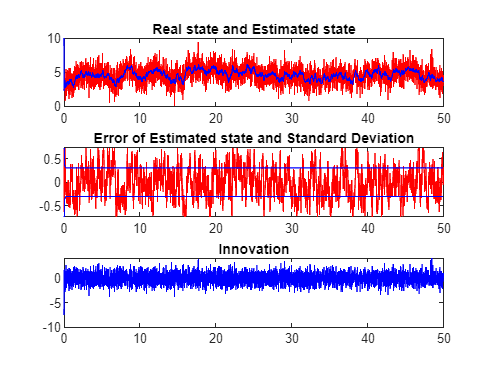

figure

subplot(311)
plot(t, x_k, 'g'); % state trajectory
hold on
plot(t, z_k, 'r'); % output trajectory
plot(t, x_cor, 'b'); % state estimation
ylim([0 10])
title('Real state and Estimated state')

subplot(312)
plot(t, x_cor - x_k, 'r'); % estimation error
hold on
plot(t, +stdx_cor, 'b'); % + standard deviation
plot(t, -stdx_cor, 'b'); % - standard deviation
ylim([-max(stdx_cor(10:end))*2 +max(stdx_cor(10:end))*2])
title('Error of Estimated state and Standard Deviation')

subplot(313)
plot(t, innov, 'b'); % Innovation
title('Innovation')